# Weeks 6-7 Workshop - Frequency Domain Filters

Note the the first part of this workshop is not assessable (Part 1-3). The second part of this workshop is assessable (Parts 4-6) and is due at 11:59 pm on Sunday 12th September at the end of Week 7.  

In workshops in Weeks 6 and 7 you will compare different filters designed in the frequency domain and identify the advantages and disadvantages of each type. By the end of Week 7 you should have applied filters to obtain two sets of clean data. 

- LFP: Local field potential - low pass upper cutoff 400Hz

- MUA: Multiunit activity/spike activity - bandpass low cut off 400 Hz, upper cutoff 14250 Hz

## 1. Load data

Load data as per previous weeks from 'datafile004'. We will use data on channel 4 only in these workshops and only the first 61 s. For simplicity you may leave the voltage signal in its native units (no need to divide by 4 to obtain microvolts) and use arbitrary units (a.u.) for the voltage units when labelling graphs.

% set wd
%dataPath = '/Users/isabelledale/Documents/raw-data';
dataPath = 'C:\Users\vid15\Documents\MATLAB\Signal Processing\NPMK-master\NPMK';
datafile = 'datafile004';

%  generate path to the NEV data file containing triggers and spike times
pathNEV = fullfile(dataPath, [datafile, '.nev']); 

%  generate path to the ns6 data file containing containing raw data
pathNS6 = fullfile(dataPath, [datafile, '.ns6']);               

% load files
NEV = openNEV(pathNEV, 'read', 'nosave');
ns6 = openNSx(pathNS6, 'read','uv');

% extract signal
f_s           = ns6.MetaTags.SamplingFreq;       % sampling frequency (Hz)
iChannel      = 4;                               % one channel to read
voltageSignal = ns6.Data(iChannel,1:61*f_s );    % voltage signal (uv)
t             = (1:length(voltageSignal))./f_s;  % time (s)

T = 1/f_s;                        % sampling period

## 2. Design frequency domain filters for LFP (Not assessed)

Design and implement a Butterworth lowpass IIR filter for the LFP signal. Use the following analog specifications for the filter to calculate the required filter order and cutoff frequency: passband frequency $f_{ps}$ = 300 Hz, stopband frequency $f_{st}$ = 800Hz, passband ripple $\alpha_{ps}$ = 0.25 dB, stopband ripple $D_{st}$ = 30 dB (You may use the inbuilt Matlab function 'butter' to obtain the filter coeficients, but read the Matlab documention carefully first. This function uses the bilinear transform and prewarps the frequencies for you). 

**Figures**

- Figure 1a, subplot(2,1,1): Plot the magnitude of the frequency response for the filter. Limits: x-limits [0 800] Hz, y-limits [-40 0] dB. 

- Figure 1b,subplot(2,1,2): Plot the phase of the frequency response for the filter. Limits: x-limits [0 800] Hz, y-limits $[-\pi, \pi]$  rad. 

- Figure 2a,  subplot(2,2,1): Plot both the raw signal and the filtered signal on the window. Limits: x limits (30 60)[s], y limits (-500 2000) [a.u.].

- Figure 2b,  subplot(2,2,2): Plot the raw signal and the filtered signal on the window. Limits: x limits (30.18 30.2)[s]. Shift the filtered signal using a y-offset of 200[a.u.] .

- Figure 2c,  subplot(2,2,3): Plot the  magnitude (in dB) of fft of both the raw and filtered signals in a low frequency band (0 800) [Hz]

- Figure 2d,  subplot(2,2,4): Plot the  magnitude (in dB) of fft of both the raw and filtered signals in a high frequency band (14500 15000) [Hz]

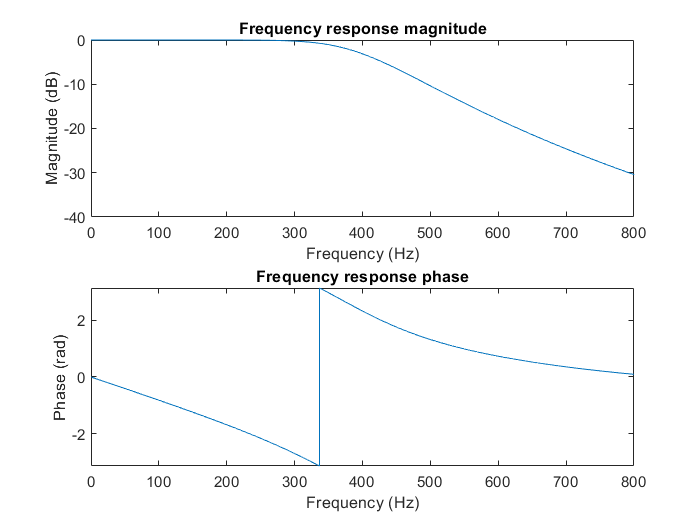

% numberof samples
N_samples = length(t);

% passband freq
f_ps = 300; % Hz
w_ps = 2*pi*f_ps/f_s; % normalised angular freq
omega_ps = 2*f_s*tan(w_ps/2); % warping

% stopband freq
f_st = 800; % Hz
w_st = 2*pi*f_st/f_s; % normalised angular freq
omega_st = 2*f_s*tan(w_st/2); % warping

% ripples
D_st = 30;
alpha_ps = 0.25;

% filter order
N = ceil((log10(10^(D_st/10) - 1) - log10(10^(alpha_ps/10) - 1))/(2*log10(omega_st/omega_ps)));

% cut-off freq
omega_c = (10^(alpha_ps/10) - 1)^(-1/(2*N))*omega_ps;
w_c = 2*atan(omega_c/2/f_s); % normalsied cut-off freq

% Butterworth filter
% fraction of normalised Nyquist
w_n = w_c/pi; 

% order of the filter
L = N + 1; 

% filter
[B, A] = butter(L-1, w_n); 

% normalised angular frequency
w = pi*(0:floor(N_samples/2))/(N_samples/2); 

% filter freq response
H = (B*exp(-1i*(0:L-1)'*w))./ (A*exp(-1i*(0:L-1)'*w));

% positive frequency vector
f_Hz = (f_s/2)*(0:floor(N_samples/2))/(N_samples/2); 

% figure 1
figure(1);

% frequency response magnitude
subplot(2, 1, 1);
plot(f_Hz, 20*log10(abs(H)));
xlim([0 800]);
ylim([-40 0]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency response magnitude');

% frequency response phase
subplot(2, 1, 2);
plot(f_Hz, angle(H));
xlim([0 800]);
ylim([-pi pi]);
xlabel('Frequency (Hz)');
ylabel('Phase (rad)');
title('Frequency response phase');

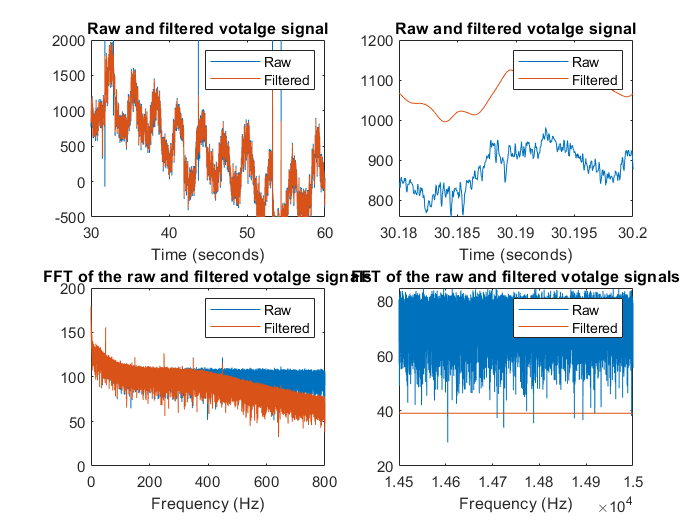


% filtered voltage signal
voltageSignal_filtered = filter(B, A, voltageSignal);

% figure 2
figure(2);

% raw and filtered signal
subplot(2, 2, 1);
plot(t, voltageSignal);
hold on
plot(t, voltageSignal_filtered);
xlim([30 60]);
ylim([-500 2000]);
xlabel('Time (seconds)');
title('Raw and filtered votalge signal');
legend('Raw', 'Filtered');
hold off

% raw and filtered signal with an offset
subplot(2, 2, 2);
plot(t, voltageSignal);
hold on
plot(t, voltageSignal_filtered + 200);
xlim([30.18 30.2]);
xlabel('Time (seconds)');
title('Raw and filtered votalge signal');
legend('Raw', 'Filtered');
hold off

% raw and filtered signal fft in dB
subplot(2, 2, 3);

% fft of the raw voltage signal
voltageSignal_hat = fft(voltageSignal);

% fft of the filtered voltage siganl
voltageSignal_filtered_hat = fft(voltageSignal_filtered);

plot(f_Hz, 20*log10(abs(voltageSignal_hat(1:floor(N_samples/2)+1))));
hold on
plot(f_Hz, 20*log10(abs(voltageSignal_filtered_hat(1:floor(N_samples/2)+1))));
xlim([0 800]);
xlabel('Frequency (Hz)');
title('FFT of the raw and filtered votalge signals');
legend('Raw', 'Filtered');
hold off

% raw and filtered signal fft in dB
subplot(2, 2, 4);
plot(f_Hz, 20*log10(abs(voltageSignal_hat(1:floor(N_samples/2)+1))));
hold on
plot(f_Hz, 20*log10(abs(voltageSignal_filtered_hat(1:floor(N_samples/2)+1))));
xlim([14500 15000]);
xlabel('Frequency (Hz)');
title('FFT of the raw and filtered votalge signals');
legend('Raw', 'Filtered');
hold off

## 3. Interpretation of filter designed for LFP signal (not assessed)

Discuss and answer the following questions:

- **Q:** Noise - What noise has been removed/attenuated and what noise remains? 

- **Q: **Signal - What signal should be preserved here? Comment on the different ways you expect the signal has been altered by the filtering (i.e., delays and phase distortion).

## 4. Design frequency domain filters for MUA (Assessable: 15 marks)

Design, implement, and compare the following two filters for the MUA signal with bandpass lower cut off frequency 400Hz, and upper cutoff frequency 14250 Hz.

- An Ideal Bandpass FIR filter of length 100 with a Hann windowing function. 

- A bandpass Butterworth IIR filter of length 7. (You may use the inbuilt Matlab function 'butter' to obtain the filter coeficients in a 1-step calculation. This function uses the bilinear transform and prewarps the frequencies for you. Read the Matlab documention carefully first) 

% ideal bandpass FIR filter
% normalised lower cut-off freq
w_c_l = 2*pi*400/f_s;
K_l = w_c_l/pi/2; % fraction of the freq
w_c_l_n = w_c_l/pi; % lower freq for butter()

% normalised upper cut-off freq
w_c_u = 2*pi*14250/f_s;
K_u = w_c_u/pi/2; % fraction of the freq
w_c_u_n = w_c_u/pi; % upper freq for butter()

% filter length
L_FIR = 100;

% filter
n = (1:L_FIR) - floor(L_FIR/2); % shifting
B_FIR = (w_c_u/pi)*sinc(n*w_c_u/pi) - (w_c_l/pi)*sinc(n*w_c_l/pi);

% Hann windowing
B_FIR = hann(L_FIR)'.*B_FIR;

% FIR freq response
H_FIR = B_FIR*exp(-1i*(0:L_FIR-1)'*w);

% ideal rect freq response
H_FIR_rect = ones(1,length(w));
H_FIR_rect(1:floor(length(w)*K_l*2)) = 1e-5;
H_FIR_rect(floor(length(w)*K_u*2):end) = 1e-5;
H_FIR_rect = H_FIR_rect.*exp(-1i*floor(L_FIR/2)*w);

% bandpass Butterworth IIR filter
% filter length
L_IIR = 7;

% butterworth filter
[B_IIR, A_IIR] = butter((L_IIR-1)/2, [w_c_l_n, w_c_u_n], 'bandpass');

% freq response
H_IIR = (B_IIR*exp(-1i*(0:L_IIR-1)'*w))./ (A_IIR*exp(-1i*(0:L_IIR-1)'*w));

**Figures** 

Filter Frequency response: 

- Figure 3a, subplot(2,1,1): Visualise the magnitude of the frequency response for the FIR filter, the IIR filter and the ideal FIR filter function based on rect(x). Use x-limits between 0 and 5000 Hz, y-limits between -100 dB and 0 dB. Be sure to include a legend.

- Figure 3b, subplot(2,1,2): Visualise the phase of the frequency response for the FIR filter, the IIR filter and the ideal FIR filter function  based on rect(x). Use x-limits between 0 and 5000 Hz, y limits between -100 dB and 0 dB.

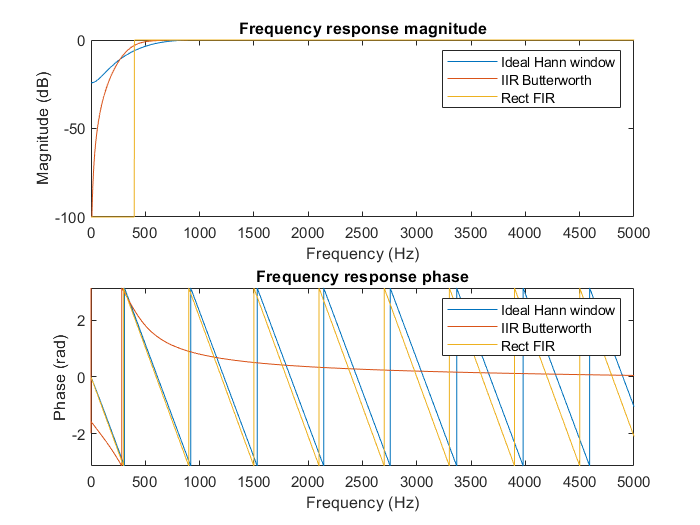

% figure 3
figure(3);

% filter magnitude plotting
subplot(2, 1, 1);
plot(f_Hz, 20*log10(abs(H_FIR)));
hold on
plot(f_Hz, 20*log10(abs(H_IIR)));
hold on
plot(f_Hz, 20*log10(abs(H_FIR_rect)));
xlim([0 5000]);
ylim([-100 0]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency response magnitude');
legend('Ideal Hann window', 'IIR Butterworth', 'Rect FIR');
hold off

% filter phase plotting
subplot(2, 1, 2);
plot(f_Hz, angle(H_FIR));
hold on
plot(f_Hz, angle(H_IIR));
hold on
plot(f_Hz, angle(H_FIR_rect));
xlim([0 5000]);
ylim([-pi pi]);
xlabel('Frequency (Hz)');
ylabel('Phase (rad)');
title('Frequency response phase');
legend('Ideal Hann window', 'IIR Butterworth', 'Rect FIR');
hold off

FIR Filtered Signals:

- Figure 4a, subplot(2,2,1): Plot both the raw signal and the FIR filtered signal on the same window: x-limits (30 60)[s], y-limits (-500 2000) [a.u.]. Be sure to include a legend.

- Figure 4b, subplot(2,2,2): Plot the raw signal and the FIR filtered signal on the window x-limits (30.18 30.2)[s]. Shift the filtered signal using a y-offset of 200 [a.u.] and y-lim [-500 2000].

- Figure 4c, subplot(2,2,3): Plot the magnitude (in dB) of fft of both the raw and filtered signals in a low frequency band (0 800) [Hz]

- Figure 4d, subplot(2,2,4): Plot the magnitude (in dB)  of fft of both the raw and filtered signals in a high frequency band (14500 15000) [Hz]

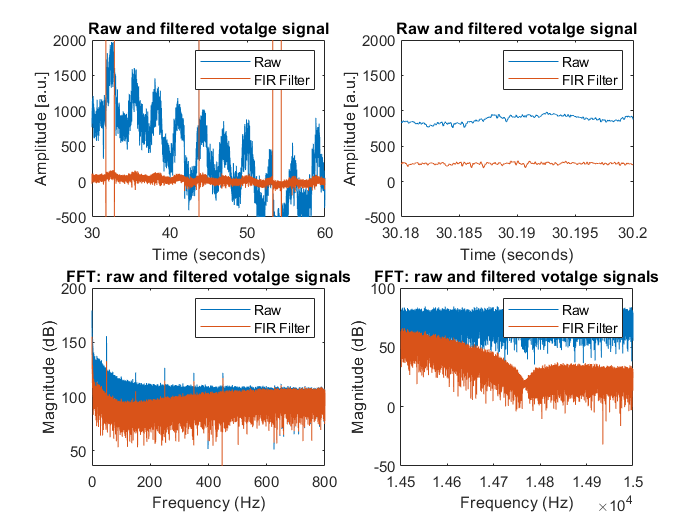

% figure 4
figure(4);

% raw and filtered signal
subplot(2, 2, 1);
plot(t, voltageSignal);
hold on
plot(t, filter(B_FIR, 1, voltageSignal));
xlim([30 60]);
ylim([-500 2000]);
xlabel('Time (seconds)');
ylabel('Amplitude [a.u.]');
title('Raw and filtered votalge signal');
legend('Raw', 'FIR Filter');
hold off

% raw and filtered signal with an offset
subplot(2, 2, 2);
plot(t, voltageSignal);
hold on
plot(t, filter(B_FIR, 1, voltageSignal) + 200);
xlim([30.18 30.2]);
ylim([-500 2000]);
xlabel('Time (seconds)');
ylabel('Amplitude [a.u.]');
title('Raw and filtered votalge signal');
legend('Raw', 'FIR Filter');
hold off

% raw and filtered signal fft in dB
subplot(2, 2, 3);

% fft of the filtered voltage siganl
voltageSignal_filtered_hat_FIR = fft(filter(B_FIR, 1, voltageSignal));

plot(f_Hz, 20*log10(abs(voltageSignal_hat(1:floor(N_samples/2)+1))));
hold on
plot(f_Hz, 20*log10(abs(voltageSignal_filtered_hat_FIR(1:floor(N_samples/2)+1))));
xlim([0 800]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('FFT: raw and filtered votalge signals');
legend('Raw', 'FIR Filter');
hold off

% raw and filtered signal fft in dB
subplot(2, 2, 4);
plot(f_Hz, 20*log10(abs(voltageSignal_hat(1:floor(N_samples/2)+1))));
hold on
plot(f_Hz, 20*log10(abs(voltageSignal_filtered_hat_FIR(1:floor(N_samples/2)+1))));
xlim([14500 15000]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('FFT: raw and filtered votalge signals');
legend('Raw', 'FIR Filter');
hold off

Butterworth Filtered Signals:

- Figure 5: same as Figure 4 but for the IIR Butterworth filter. 

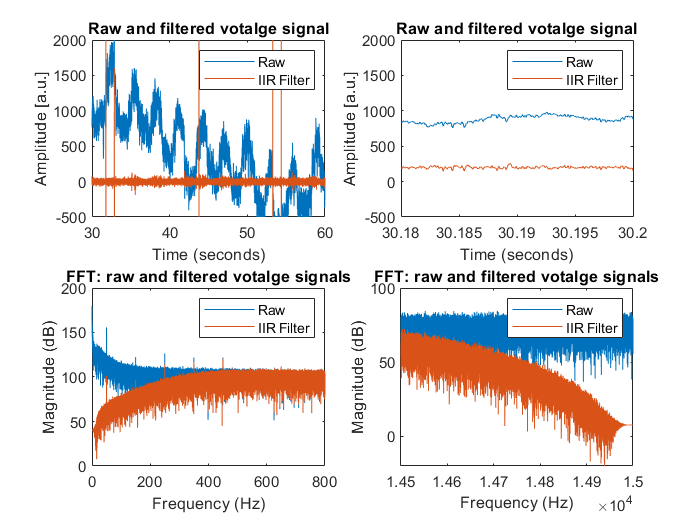

% figure 5
figure(5);

% raw and filtered signal
subplot(2, 2, 1);
plot(t, voltageSignal);
hold on
plot(t, filter(B_IIR, A_IIR, voltageSignal));
xlim([30 60]);
ylim([-500 2000]);
xlabel('Time (seconds)');
ylabel('Amplitude [a.u.]');
title('Raw and filtered votalge signal');
legend('Raw', 'IIR Filter');
hold off

% raw and filtered signal with an offset
subplot(2, 2, 2);
plot(t, voltageSignal);
hold on
plot(t, filter(B_IIR, A_IIR, voltageSignal) + 200);
xlim([30.18 30.2]);
ylim([-500 2000]);
xlabel('Time (seconds)');
ylabel('Amplitude [a.u.]');
title('Raw and filtered votalge signal');
legend('Raw', 'IIR Filter');
hold off

% raw and filtered signal fft in dB
subplot(2, 2, 3);

% fft of the filtered voltage siganl
voltageSignal_filtered_hat_IIR = fft(filter(B_IIR, A_IIR, voltageSignal));

plot(f_Hz, 20*log10(abs(voltageSignal_hat(1:floor(N_samples/2)+1))));
hold on
plot(f_Hz, 20*log10(abs(voltageSignal_filtered_hat_IIR(1:floor(N_samples/2)+1))));
xlim([0 800]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('FFT: raw and filtered votalge signals');
legend('Raw', 'IIR Filter');
hold off

% raw and filtered signal fft in dB
subplot(2, 2, 4);
plot(f_Hz, 20*log10(abs(voltageSignal_hat(1:floor(N_samples/2)+1))));
hold on
plot(f_Hz, 20*log10(abs(voltageSignal_filtered_hat_IIR(1:floor(N_samples/2)+1))));
xlim([14500 15000]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('FFT: raw and filtered votalge signals');
legend('Raw', 'IIR Filter');
hold off

## 5. Interpretation of filters designed for MUA signal (10 marks)

Discuss and answer the following questions:

- **Q:** Noise - What noise has been removed/attenuated and what noise remains? Compare the performance of the two filters. 

Noise removed: Noise below 400Hz and above 14250Hz is being attenuated, which includes powerline interference at 50Hz, and its harmonics at 150Hz, 250Hz and 350Hz, LFP, muscle contraction artifacts at 60Hz, heart rate and respiration artifacts, as well as alpha, beta, theta, delta and gamma waves. 

Noise preserved: thermal noise, neural spikes, MUA, some of the powerline interference harmonics and the very fast ripples at around 800Hz and 900Hz. 

Filter comparison: Butterworth filter presents a sharper attenuation than ideal band pass filter with a Hann windowing. This means that motions artifacts as well as other noises are better attenuated in the Butterworth filter. With that being said, ideal FIR filter still does a good job at signal attenuation, just not as harsh 

- **Q:** Signal - What signal should be preserved here? How well is each fitlered signal preserving spikes? In particular, comment on the spike triplet (30.183s, 30.186s, 30.189s) in the filtered signal in Fig 2b and Fig 3b (subplot 2 in each). Compare the spike shapes and delay times of the two filtered signals with the raw signal. 

MUA should be well-preserved. For the Butterworth filter there is a strong evidence of phase distortion, as the phase response is non-linear, when compared to the ideal FIR (with linear phase response). Both filters present phase delay as well. The ideal FIR has introduced a time delay of 1.6ms, while the Butterworth filter produced not significant time delay (at least I cannot see any). The IIR filter, however, smoothed out the peaks (or "squared-off"), which makes peak identification rather difficult. As for the FIR filter no visible smoothing of the signal was detected.   

- **Q:** Time - Add code to start and stop a timer for the filtering step (i.e. the 'filter' command) of each filter (Hint: use 'tic' and 'toc') . Compare the time required to perform each type filtering, comment on time.

% Butterworth IIR filtering
tStart_IIR = tic;
filtering_IIR = filter(B_IIR, A_IIR, voltageSignal);
tStop_IIR = toc(tStart_IIR);

% Ideal FIR filtering
tStart_FIR = tic;
filtering_FIR = filter(B_FIR, 1, voltageSignal);
tStop_FIR = toc(tStart_FIR);

Filtering time for the Butterworth filter was determined to be 0.0332 seconds, while the for ideal FIR - 0.0311. This means that Butterworth filtering takes longer, than the FIR, which is logical, since it is the IIR response (meaning there is a feedback to account for (implicit impulse response)). 

- **Q:** Discuss the advantages and disadvantages of each filter type. If the filter could be run in off-line mode (i.e. not in real time) how could you improve each filter? 

FIR advantages: stability, linear phase response, easy to implement

FIR disadvantages: requires large data storage

IIR advantages: minimal effective delay, computationally less demanding

IIR disadvantages: phase distortion, potentially unstable

## 6. Assignment Submission

BMEN90035WorkshopWeek6.mlx from canvas will serve as both your code and report file. Write your solutions in this file format and then publish this to a .pdf file. Please submit the following:

- The matlab code file ‘.mlx’ with file name ‘A4studentno.m’.

- The published matlab report with file name ‘A4studentno.pdf’. Use the inbuilt publish function in matlab to create a published version of the matlab code file. 

- A single file of any scanned mathematical derivations/solutions with file name ‘A4mstudentno.pdf’